# 2D primary mixed-mode SSM for the dynamic buckling of a beam

In this example, we apply a sufficiently large axial compression force to a pinned-pinned von Kármán beam [1] and seek to derive an SSM-reduced nonlinear model for the ensuing buckling dynamics [2].

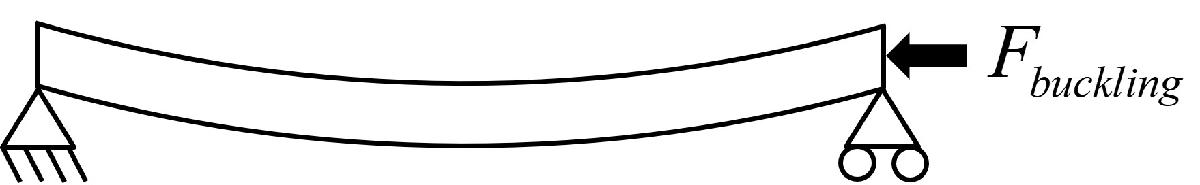

[1] S. Jain, P. Tiso, and G. Haller, Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds, *Journal of Sound and Vibration* 423 (2018) 195-211. [https://doi.org/10.1016/j.jsv.2018.01.049](https://doi.org/10.1016/j.jsv.2018.01.049)

[2] G. Haller, B. Kaszás, A. Liu and J.Axås, Data-Driven Nonlinear Model Reduction to Fractional and Mixed-Mode Spectral Submanifolds, to be submitted.

clearvars
close all
addpath tools

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

Building FE model


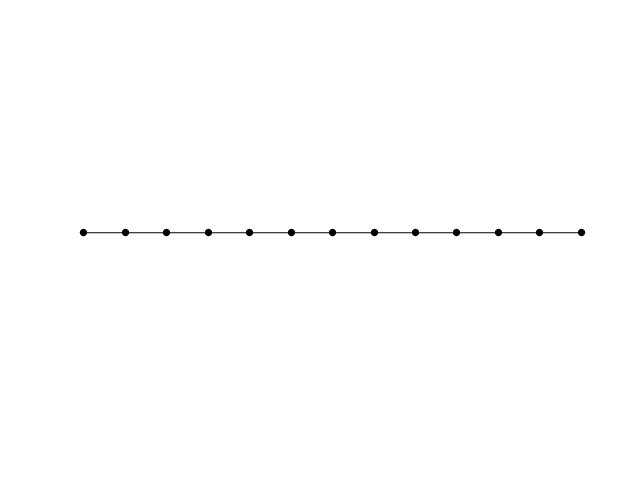

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


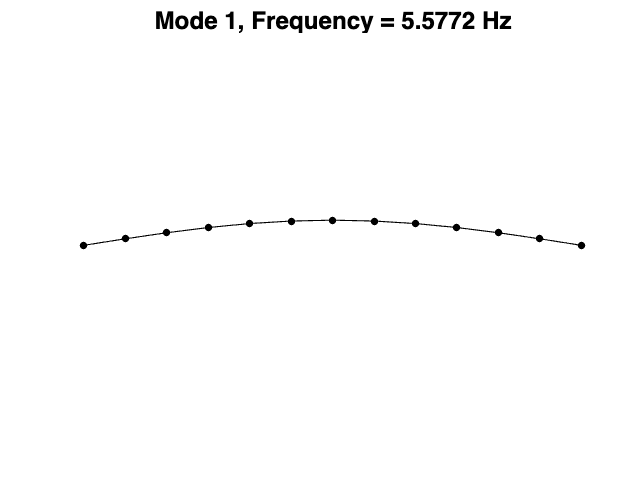

Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:04


nElements = 12;
l = 2; h = 1e-2; b = 5e-2; % Mesh parameters
E = 190e9;  % Young's modulus
[M, C, K, fnl, fExt, obsdof, PlotFieldonDefMesh] = buildModelBuckling(nElements,l,h,b,E);

n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

We apply buckling force larger than Euler's critical load


$$F = \frac{N^2 \pi ^2 EI}{L^2} = \frac{\pi ^2 Ebh^3}{12 L^2}$$


loads = [1.45]*pi^2* E * b*(h)^3 /12 / l^2;  %lets increase the load
loadvector = loads.*fExt;
[F_0, ~] = functionFromTensors(M, C, K, fnl);
unstable_fp = getStaticResponseIC(K, M, F_0, -loadvector, 0, PlotFieldonDefMesh); 
%unstable_fp = unstable_fp(1:36,:);

%[Ktilde, f1tilde, f2tilde] = functFromTensorsSFP(M, C, K, fnl, loadvector, unstable_fp);

Building FE model


Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00



[M, C, K, fnl, fExt, obsdof, PlotFieldonDefMesh] = buildModelBuckling(nElements,l,h,b,E);


[K_shift,fnl_shift ] = build_model_shift(K, fnl, unstable_fp);

DS = DynamicalSystem(2);
set(DS,'M',M,'C',C,'K',K_shift,'fnl',fnl_shift);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 3.233964e-03
modal damping ratio for 3 mode is 6.344352e-03
modal damping ratio for 4 mode is 1.083855e-02
modal damping ratio for 5 mode is 1.665763e-02

 The first 10 nonzero eigenvalues are given as 
   1.0e+02 *

   0.2348 + 0.0000i
  -0.0036 + 1.1192i
  -0.0036 - 1.1192i
  -0.0183 + 2.8894i
  -0.0183 - 2.8894i
  -0.0580 + 5.3511i
  -0.0580 - 5.3511i
  -0.1419 + 8.5190i
  -0.1419 - 8.5190i
  -0.2353 + 0.0000i



S = SSM(DS);
set(S.Options, 'reltol', 100,'notation','multiindex', 'paramStyle', 'graph')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,10]; 
S.choose_E(masterModes);

sigma_out = 0
sigma_in = -1


[W0, R0] = S.compute_whisker(18);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.54E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 7.77E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.09E-01 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.53E-01 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 2.11E-01 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 2.87E-01 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 3.82E-01 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 4.98E-01 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 6.38E-01 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 8.04E-01 MB
Manifold computation time 

%save('vonkarman_buckled_mid_load_order18.mat', 'W0', 'R0')


rhs_reduced = @(x) tpoly(R0, x);

one = fsolve(rhs_reduced, [1e-2, 1e-2]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



two = fsolve(rhs_reduced, [-1e-2, -1e-2]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


one

one = 1.0e-19 *

   -0.1101   -0.1101


two

two = 1.0e-19 *

    0.1101    0.1101


## Simulate trajectories as in Liu et al:

%[~, lambda, ~] = functionFromTensorsFP(M, C, K, fnl, loadvector, unstable_fp);
[F, ~] = functionFromTensors(M, C, K, fnl, loadvector, 0);

newMeasurement = true; % true
observable = @(x) x; % observe full system
lambda = D(1,1);
%slowTimeScale = 2*pi/abs(lambda(1));
%[F_0, lam, V_, W_, ~] = functionFromTensors(M, C, K_shift, fnl_shift, -loadvector, 0);

newMeasurement = false;
if newMeasurement
    z0 = 1e-5;
    q0_plus = reduced_to_full_traj(0,[z0; 0],W0);
    q0_shifted_plus = q0_plus + unstable_fp;

    q0_minus = reduced_to_full_traj(0,[-z0; 0],W0);
    q0_shifted_minus = q0_minus + unstable_fp;

    timespan = linspace(0,2,2000);
    options = odeset('RelTol',1e-8,'AbsTol',1e-10);

    %tr_ssm = transient_traj_on_auto_ssm(DS, [1,10], W0, R0, 10, 1000, 1:72, q0);
    [~, sol_plus] = ode45(F, timespan, q0_shifted_plus, options);
    [~, sol_minus] = ode45(F, timespan, q0_shifted_minus, options);
    DataInfo = struct('nElements', nElements, 'loadvector', loadvector, 'unstable_fp', unstable_fp);
    save('dataVK_buckled_unforced_mid.mat', 'DataInfo',  'sol_plus', 'sol_minus', 'unstable_fp');
else
    load dataVK_buckled_unforced_mid.mat
    if nElements ~= DataInfo.nElements
        error('The loaded data comes from a model with a different number of elements.')
    end
end

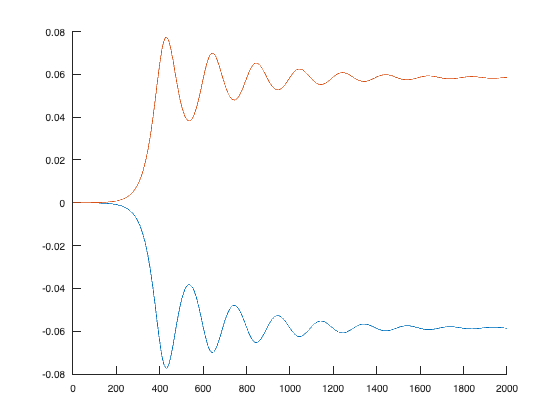

figure;
hold on; 
plot(sol_plus(:, obsdof+1))
plot(sol_minus(:, obsdof+1))

stable_fp = sol_plus(end, :);

Add the periodic forcing

options = odeset('RelTol',1e-6,'AbsTol',1e-6);



f_periodic  = zeros(size(fExt)); f_periodic(18,1) = 1; % forcing on midpoint
Amp = 1.2116*5.1258*3.4; Frq = 25.30769231;%23.957894736842107; % forcing amplitude and frequency in full state space

F_f = Amp.*(M\f_periodic);
F_forced = @(t,x,w) F(t,x) + [zeros(n,1); F_f*cos(w*t)];

x0_ep1 = ic_ + unstable_fp;%stable_fp; % initial conditions
x0_ep2 = ic_ + unstable_fp; 
x0_ep2(18) = x0_ep2(18) + 1e-4; % add a small perturbation to the IC

slowTimeScale = 2*pi/Frq;
numberPeriods = 200;  
numberPointsPerPeriod = 100; 
endTime = numberPeriods*slowTimeScale;
nSamp = numberPeriods*numberPointsPerPeriod+1;
dt = endTime/(nSamp-1);
timespan = [0:dt:endTime];

[~, sol_ep1] = ode15s( @(t,x) F_forced(t,x,Frq), timespan, x0_ep1, options  );
[~, sol_ep2] = ode15s( @(t,x) F_forced(t,x,Frq), timespan, x0_ep2,options);

load('buckled_chaotic_IC.mat')

% the amplitude was selected from a chaotic Pade-model
f_periodic  = zeros(size(fExt)); f_periodic(18,1) = 1; % forcing on midpoint
Amp = 1.2116*5.1258*3.4; Frq = 25.30769231;%23.957894736842107; % forcing amplitude and frequency in full state space

F_f = Amp.*(M\f_periodic);
F_forced = @(t,x,w) F(t,x) + [zeros(n,1); F_f*cos(w*t)];



[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 3.233964e-03
modal damping ratio for 3 mode is 6.344352e-03
modal damping ratio for 4 mode is 1.083855e-02
modal damping ratio for 5 mode is 1.665763e-02

 The first 10 nonzero eigenvalues are given as 
   1.0e+02 *

   0.2348 + 0.0000i
  -0.0036 + 1.1192i
  -0.0036 - 1.1192i
  -0.0183 + 2.8894i
  -0.0183 - 2.8894i
  -0.0580 + 5.3511i
  -0.0580 - 5.3511i
  -0.1419 + 8.5190i
  -0.1419 - 8.5190i
  -0.2353 + 0.0000i



left_eig = W(:, [1,10]);
left_eig(:,1) = left_eig(:,1)/norm(left_eig(:,1));
left_eig(:,2) = left_eig(:,2)/norm(left_eig(:,2));

right_eig = V(:, [1,10]);

f_ext_vector = [zeros(n,1); F_f];
left_eig'*DS.B*f_ext_vector

ans =     0.1862
   -0.1859



reduced = left_eig'*DS.B*sol_ep1';

Unrecognized function or variable 'sol_ep1'.

figure;
hold on; 
%plot(reduced(1,:),reduced(2,:))
plot(timespan,sol_ep2(:, 18))
plot(timespan,sol_ep1(:, 18))


save('dataVK_buckled_forced_chaotic_mid.mat', 'Amp', 'reduced', 'Frq', 'F_f', 'M', 'sol_ep1', 'sol_ep2', 'unstable_fp');


% the amplitude was selected from a chaotic Pade-model
f_periodic  = zeros(size(fExt)); f_periodic(18,1) = 1; % forcing on midpoint
Amp = 5.1258*3.4; Frq = 23.957894736842107; % forcing amplitude and frequency in full state space

F_f = Amp.*(M\f_periodic);
F_forced = @(t,x,w) F(t,x) + [zeros(n,1); F_f*cos(w*t)];



[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 3.233964e-03
modal damping ratio for 3 mode is 6.344352e-03
modal damping ratio for 4 mode is 1.083855e-02
modal damping ratio for 5 mode is 1.665763e-02

 The first 10 nonzero eigenvalues are given as 
   1.0e+02 *

   0.2348 + 0.0000i
  -0.0036 + 1.1192i
  -0.0036 - 1.1192i
  -0.0183 + 2.8894i
  -0.0183 - 2.8894i
  -0.0580 + 5.3511i
  -0.0580 - 5.3511i
  -0.1419 + 8.5190i
  -0.1419 - 8.5190i
  -0.2353 + 0.0000i



left_eig = W(:, [1,10]);
left_eig(:,1) = left_eig(:,1)/norm(left_eig(:,1));
left_eig(:,2) = left_eig(:,2)/norm(left_eig(:,2));

right_eig = V(:, [1,10]);

f_ext_vector = [zeros(n,1); F_f];
left_eig'*DS.B*f_ext_vector

ans =     0.1537
   -0.1534


Minv = inv(M);
A = [zeros(n), eye(n);
    -Minv*K_shift,  -Minv*C];